clear;close;clc;

## Section C graphing:

## Variables

Variables of the calculation range:

ti = 0; % t initial
tf = 168; % t final
npts = 1440; % step count
t = linspace(ti,tf,npts); % full t range for output
% C  and M control the C and Mo constants in the T(t) equation, alter them
% to change the starting temperature 
Mo = 35;

## C(Mo) calculation

function C=Ccalc(Mo)
    C=100-Mo-4.308;
end

% calculate C
C = Ccalc(Mo);

## M(t) calculation

Function

function Tm = Tout(t, Mo)
    Tm = Mo - 12*cos(pi*((t-5)/12));  
end

% Matrix
M = Tout(t,Mo);

## T(t) calculation

Function

function T = Tin(t,Mo,C)
    theta = (pi*(t-5))/12;
    Th = C*(exp(-1*(t/4)));
    Tp = (36/(9+(pi^2)))*(3*cos(theta)+pi*sin(theta));
    T = Mo+Th-Tp;
end

% Matrix
T = Tin(t,Mo,C);

## Critical points

[Mmin, tMmin] = min(M);
[Mmax, tMmax] = max(M);
[Tmin, tmin] = min(T);
[Tmax, tmax] = max(T);

function timeout = minutescalc(x, t)
    time=t(x);
    hours = floor(time);
    minutes = round((60 * (time - hours)));
    % Prevents the 6 hours and 60 minutes output I was getting
    if minutes == 60
        minutes = minutes - 1;
    end
    timeout = [hours,minutes];
end

% Grabbing max and min times
tmins = [tmin, tMmin];
Tmins = [Tmin, Mmin];
tmaxs = [tmax, tMmax];
Tmaxs = [Tmax, Mmax];

% Printing max/min times
Tspoints = [Tmin, Tmax, minutescalc(tmin,t), minutescalc(tmax,t)];
Mspoints = [Mmin, Mmax, minutescalc(tMmin,t), minutescalc(tMmax, t)];
formatspec1 = 'Inside temperature: Minimums and Maxs of %2.2f and %2.2f at %2.0f:%02.0f and %2.0f:%02.0f\n';
formatspec2 = 'Outside temperature: Minimums and Maxs of %2.2f and %2.2f at %2.0f:%02.0f and %2.0f:%02.0f\n';
fprintf(formatspec1, Tspoints)

Inside temperature: Minimums and Maxs of 26.71 and 100.00 at 80:05 and  0:00


fprintf(formatspec2, Mspoints)

Outside temperature: Minimums and Maxs of 23.00 and 47.00 at 53:00 and 160:59


## Plotting

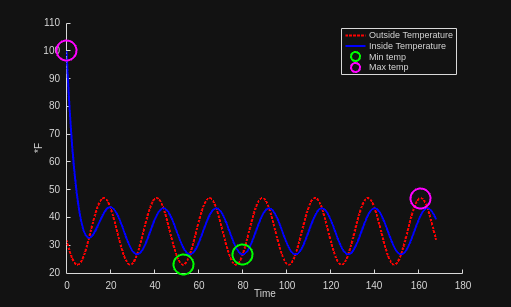

figure
hold on 
ToutPlot = plot(t,M,":r",LineWidth=3);
TinPlot = plot(t,T,"-b",LineWidth=3,MarkerSize=10);
TminPlot = plot(t(tmins),Tmins,"oG",MarkerSize=30,LineWidth=3);
TmaxPlot = plot(t(tmaxs),Tmaxs,"oM",MarkerSize=30,lineWidth=3);
xlabel("Time")
ylabel("*F")
fontsize(15,"points")
legend("Outside Temperature","Inside Temperature","Min temp","Max temp")
hold off